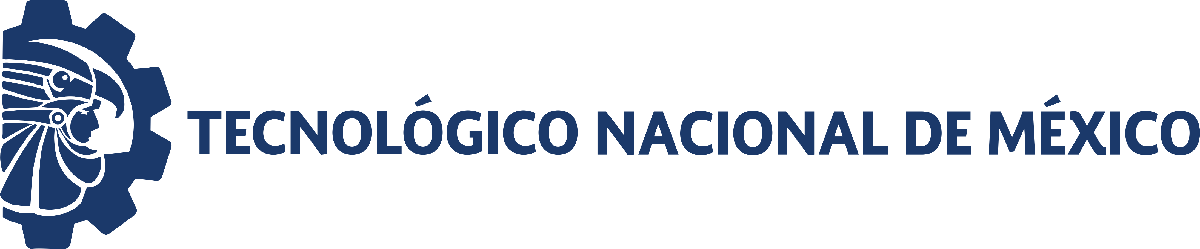                                 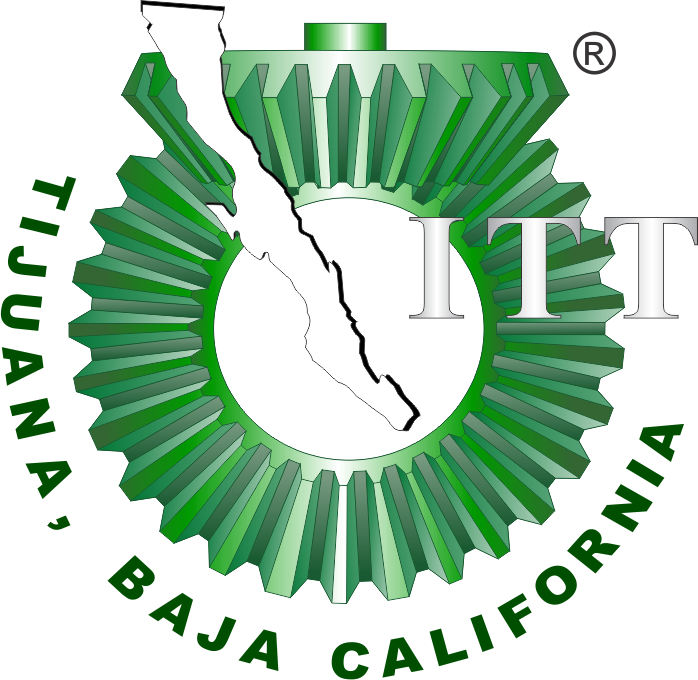

# Práctica 1: Diseno de controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

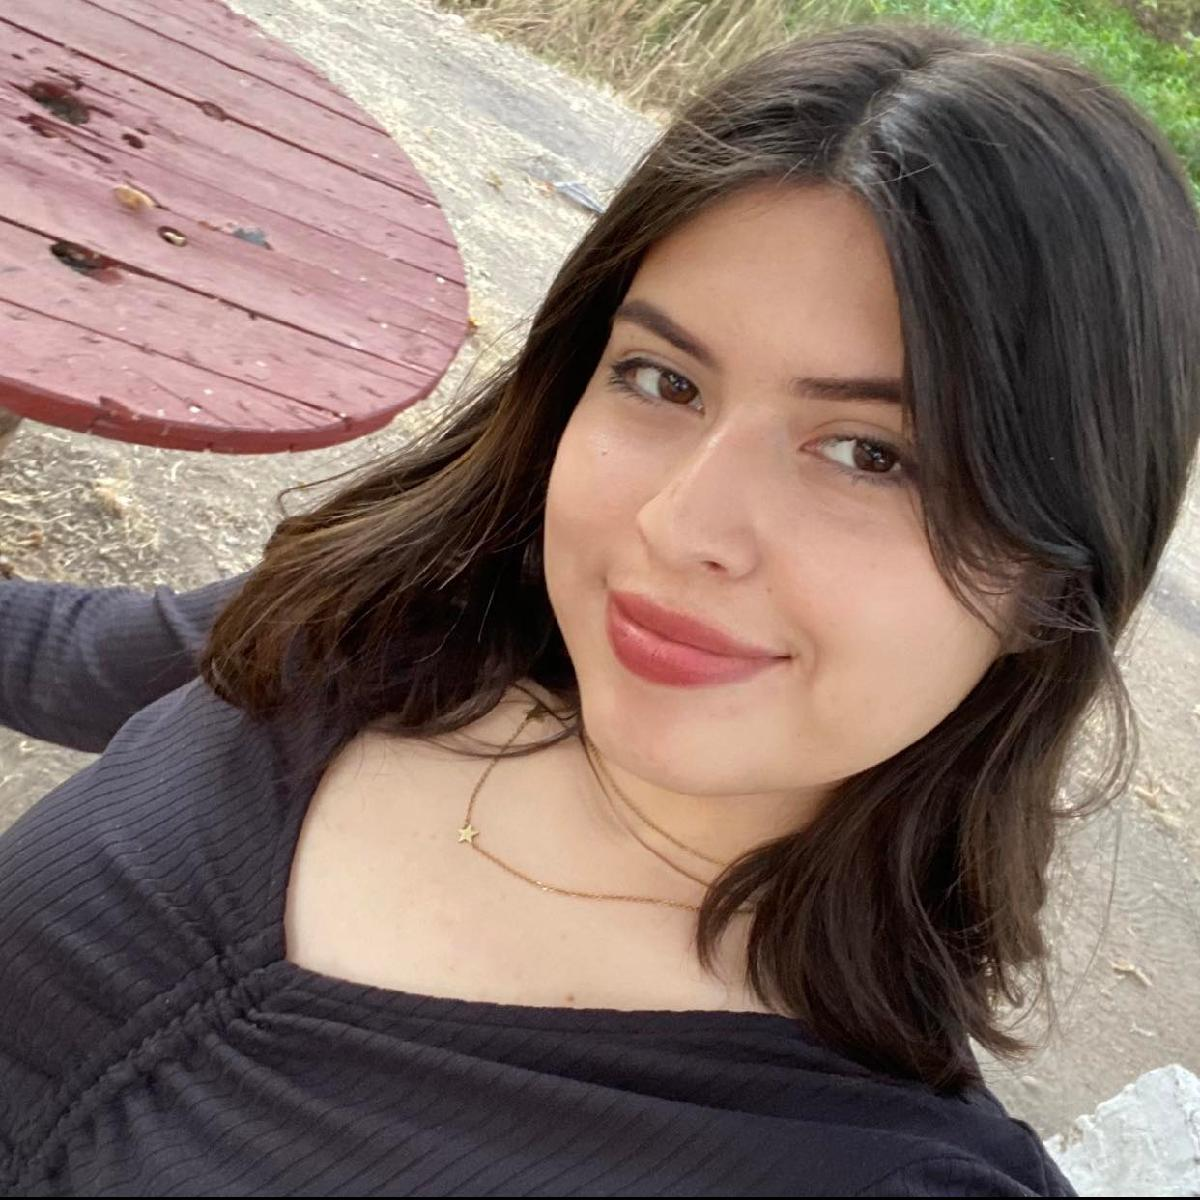

Nombre del alumno: **Lugo Valenzuela Liliana Fernanda**

Número de control: **21212165**

Correo institucional: **L21212165@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend='10';
file='SistemaU2';
open_system(file);
parameters.StopTime=tend;
parameters.Solver='ode23t';
parameters.MaxStep='1e-3';
set_param('SistemaU2/Vs1(t)','vectorFormat','1-D array');

## Respuesta al escalón

Signal='step';
set_param('SistemaU2/S1','sw','1');
set_param('SistemaU2/Ve(t)','sw','1');
x1=sim(file, parameters);

Found algebraic loop containing: 
SistemaU2/Vs3(t)/Gain4
SistemaU2/Vs3(t)/Gain2
SistemaU2/Vs3(t)/Gain1
SistemaU2/Vs3(t)/Derivative
SistemaU2/Vs3(t)/Add
SistemaU2/Vs3(t)/Gain
SistemaU2/Vs3(t)/Gain3
SistemaU2/Vs3(t)/Add1 (algebraic variable)
SistemaU2/Vs3(t)/Add2 

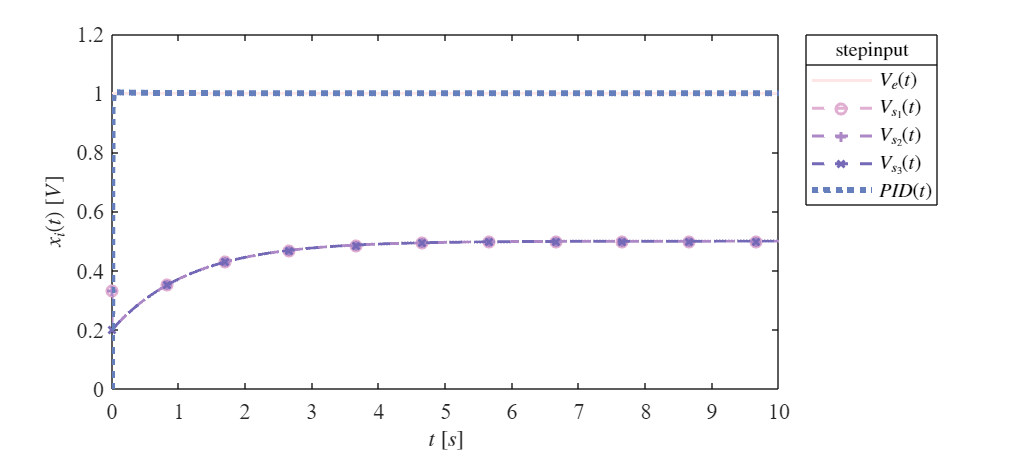

plotsignals(x1.t,x1.Ve,x1.Vs1,x1.Vs2,x1.Vs3,x1.PID,Signal)

## Respuesta al impulso

Signal='impulse';
set_param('SistemaU2/S1','sw','0');
set_param('SistemaU2/Ve(t)','sw','1');
x2=sim(file, parameters);

Found algebraic loop containing: 
SistemaU2/Vs3(t)/Gain4
SistemaU2/Vs3(t)/Gain2
SistemaU2/Vs3(t)/Gain1
SistemaU2/Vs3(t)/Derivative
SistemaU2/Vs3(t)/Add
SistemaU2/Vs3(t)/Gain
SistemaU2/Vs3(t)/Gain3
SistemaU2/Vs3(t)/Add1 (algebraic variable)
SistemaU2/Vs3(t)/Add2 

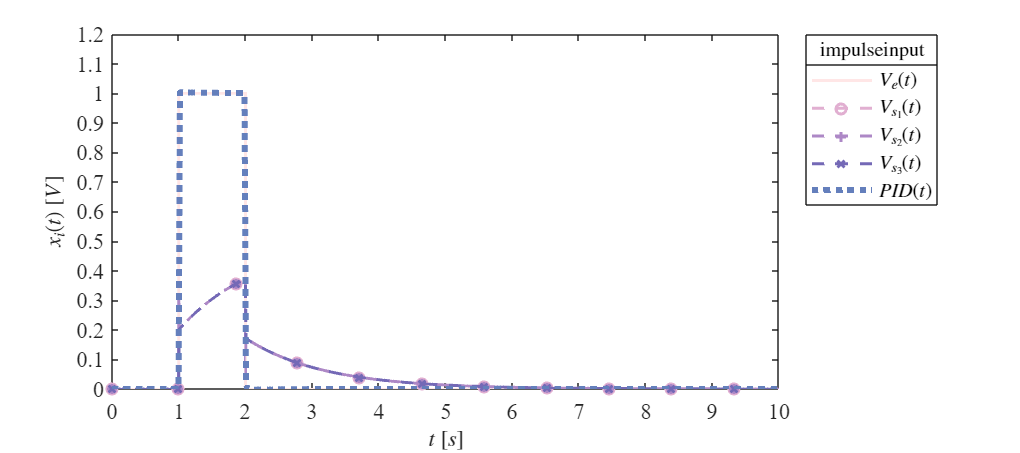

plotsignals(x2.t,x2.Ve,x2.Vs1,x2.Vs2,x2.Vs3,x2.PID,Signal)

## Respuesta a la rampa

Signal='ramp';
set_param('SistemaU2/S2','sw','1');
set_param('SistemaU2/Ve(t)','sw','0');
x3=sim(file, parameters);

Found algebraic loop containing: 
SistemaU2/Vs3(t)/Gain4
SistemaU2/Vs3(t)/Gain2
SistemaU2/Vs3(t)/Gain1
SistemaU2/Vs3(t)/Derivative
SistemaU2/Vs3(t)/Add
SistemaU2/Vs3(t)/Gain
SistemaU2/Vs3(t)/Gain3
SistemaU2/Vs3(t)/Add1 (algebraic variable)
SistemaU2/Vs3(t)/Add2 

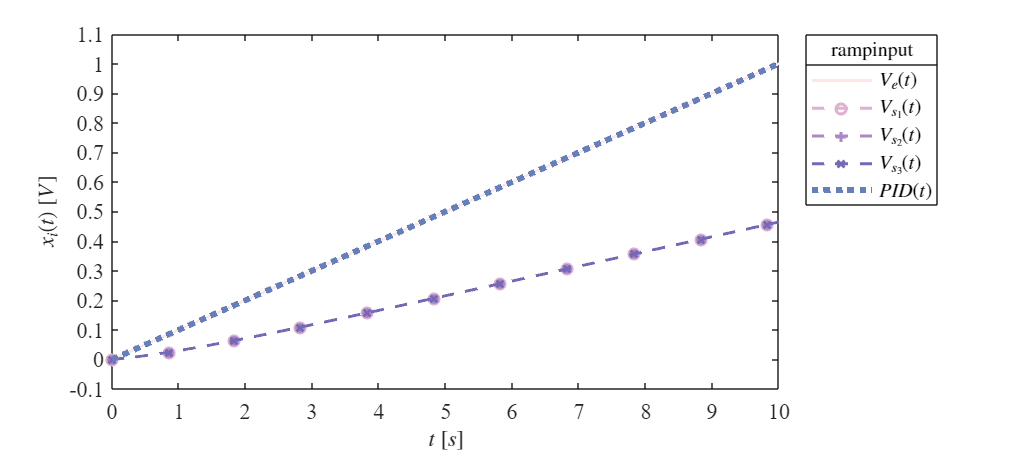

plotsignals(x3.t,x3.Ve,x3.Vs1,x3.Vs2,x3.Vs3,x3.PID,Signal)

## Respuesta a la función sinusoidal

Signal='sin';
set_param('SistemaU2/S2','sw','0');
set_param('SistemaU2/Ve(t)','sw','0');
x4=sim(file, parameters);

Found algebraic loop containing: 
SistemaU2/Vs3(t)/Gain4
SistemaU2/Vs3(t)/Gain2
SistemaU2/Vs3(t)/Gain1
SistemaU2/Vs3(t)/Derivative
SistemaU2/Vs3(t)/Add
SistemaU2/Vs3(t)/Gain
SistemaU2/Vs3(t)/Gain3
SistemaU2/Vs3(t)/Add1 (algebraic variable)
SistemaU2/Vs3(t)/Add2 

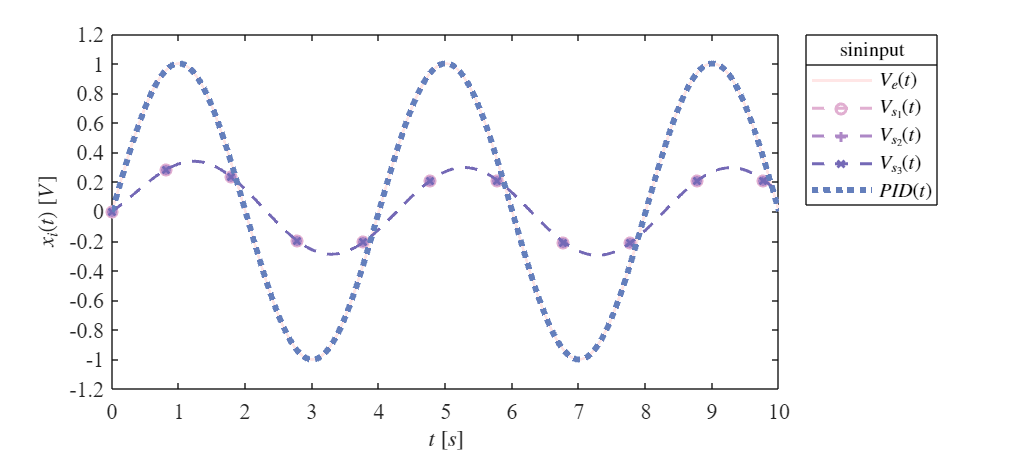

plotsignals(x4.t,x4.Ve,x4.Vs1,x4.Vs2,x4.Vs3,x4.PID,Signal)

## Funcion: Respuesta a las senales

function plotsignals(t, Ve, Vs1, Vs2, Vs3, PID, Signal)
   set(figure(), 'Color', 'w')
   set(gcf, 'units', 'centimeters', 'position', [1,1,18,8] )
   set(gca, 'FontName', 'Times New Roman', 'FontSize',11)
   hold on; grid off; box on;
   mycolors = [1.000, 0.902, 0.902;
               0.882, 0.686, 0.820;
               0.678, 0.533, 0.776;
               0.455, 0.412, 0.714;
               0.392, 0.498, 0.737;
               0.568, 0.678, 0.784;
               ];
   colororder(mycolors)




   p=plot(t, Ve, '-', t, Vs1, '--o',t,Vs2, '--+',t,Vs3,'--x',t,PID,':', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  set(p(5),'LineWidth',3);
   L = legend('$V_e(t)$', '$V_{s_1}(t)$', '$V_{s_2}(t)$', '$V_{s_3}(t)$','$PID(t)$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   title (L, [Signal, 'input'], 'FontSize',10)


   xlabel('$t$ $[s]$', 'Interpreter','Latex', 'FontSize',11)
   ylabel('$x_i(t)$ $[V]$', 'Interpreter','Latex', 'FontSize',11)

xlim([0,10]); xticks(0:1:10);
   if Signal  == "Step" || Signal=="impulse"
  
       ylim([0,1.2]); yticks(0:0.1:1.2);
     
   elseif Signal=="ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1);

 elseif Signal=="sin"
        ylim([-1.2,1.2]); yticks(-1.2:0.2:2);

end     
exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
end
